**0. Preparation**

clear,close all,clc

add other folders' path

    **! Be careful.**

    This live script must be run at the path of  "../FT-STFT-WT-HHT/WT"

    Problems or accidents will happen when current directory.

path(path, '../SourceSignal'); % raw data of experiments -- folder
path(path, '../FT');           % functions or example scripts of Fourier Transformation

load('downsample-10_sourcedata.mat');
Fs = 2000; % downsample/10
t = 0:1/Fs:size(y, 1)/Fs-1/Fs;
t = t';
size(y)

ans =       100000           1

Preview of source data

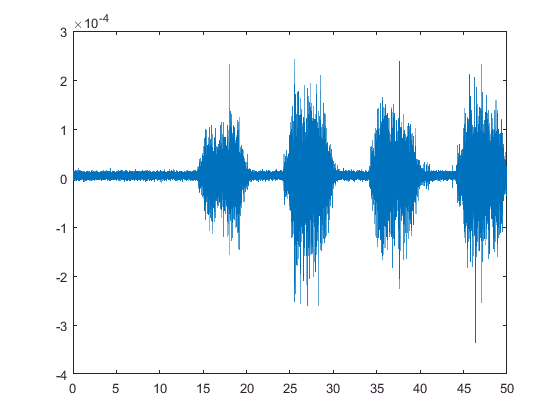

plot(t, y)

**1. Fourier Transformation**

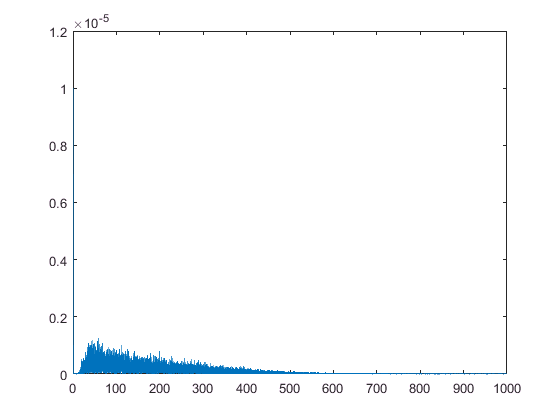

[M, P, f] = FourierAnalysis(y, Fs);
plot(f,M);

**2. CWT**

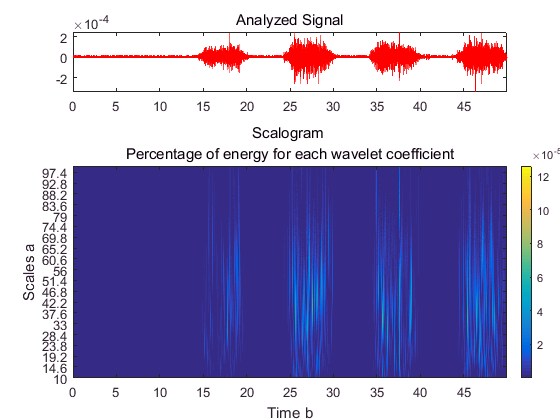

fc = centfrq('cmor1-1');
freqrange = [1 2000];
scalerange = fc./(freqrange*(1/Fs));
scales = scalerange(end):0.2:scalerange(1);
Coeffs = cwt(y, scales, 'cmor1-1');
SCImg = wscalogram('image', Coeffs, ...
                   'scales', scales, ...
                   'ydata', y, ...
                   'xdata', t);

**3. Denoising**

dwtmode('per');

                                         
*****************************************
**  DWT Extension Mode: Periodization  **
*****************************************
                                         


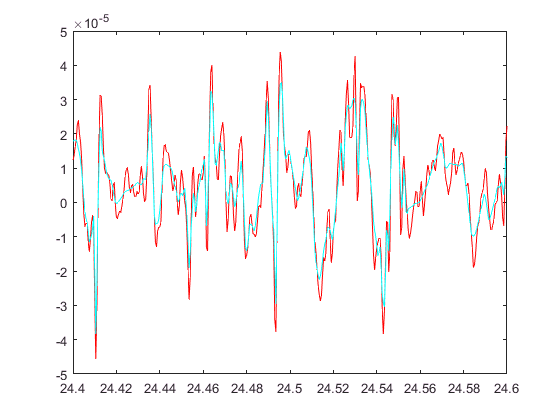

[yd, cyd,lyd] = wden(y, 'sqtwolog', 's', 'sln', 4, 'sym4');
                        % threshold 
                                    % soft
                                        %single noise estimation
                                                %4 level decomposition
                                                    % wavelet name
%yd->y-denoised.
    %coefficientsj
        %length of coefficients by level of DWT denoising
figure
plot(t, y, 'r');
hold on;
plot(t, yd, 'c')
set(gca, 'xlim', [24.4,24.6]);

**4. Nondecimated Discrete Wavelet Analysis**

    how to obtain the nondecimated-stationary wavelet transform of noisy frequency-modulated signal.

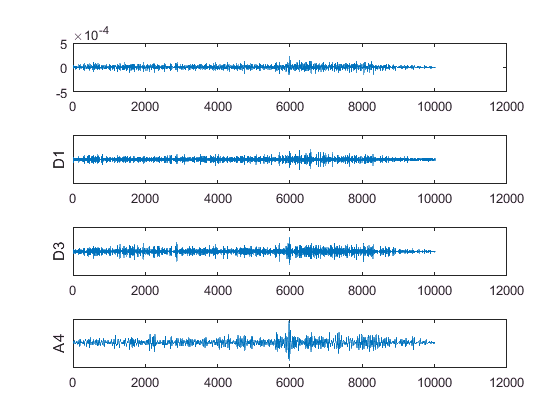

part_y = y(30000:40015);
swc = swt(part_y, 4, 'dmey');
% swt -> discrete stationary wavelet transform 1-D
% Reference to example data:noisdopp, almost perfect.

figure;
subplot(411)
plot(part_y);
subplot(412);
plot(swc(1,:)); ylabel('D1');
set(gca,'ytick',[]);
subplot(413)
plot(swc(3,:)); ylabel('D3');
set(gca,'ytick',[]);
subplot(414);
plot(swc(5,:)); ylabel('A4');
set(gca,'ytick',[]);